# CAPÍTULO 02 - CÁLCULO DE CERCHAS

Introduce nodos y conexiones para obtener desplazamientos, reacciones y esfuerzos de cada barra. N positivo indica tracción y N negativo compresión.

Dimensión: admite nodos 2D y 3D. Una cercha espacial solo transmite N; si sus uniones transmiten momentos utiliza el capítulo 7.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

nodos: una fila [x y] o [x y z]. barras: índices de los dos nodos extremos. E y F pueden ser escalares o un valor por barra. cargas: nodo y componentes de fuerza. apoyos: nodo y desplazamientos impuestos; NaN deja libre una componente. deformacionLibre admite alpha·deltaT o errores de montaje por barra.

nodos = [0 0; 2 0; 1 1.5];
barras = [1 2; 1 3; 2 3];
E = 210e9;
F = 400e-6;
cargas = [3 0 -20000];
apoyos = [1 0 0; 2 NaN 0];
deformacionLibre = 0;

## 2. Compatibilidad y equilibrio

La elongación de una barra es la proyección del desplazamiento relativo de sus extremos sobre su eje. Su rigidez axial EF/L convierte esa elongación elástica en fuerza. Las fuerzas de todas las barras se equilibran en cada nodo.


$$\varepsilon_i=\frac{\mathbf{n}_i\cdot(\mathbf{u}_b-\mathbf{u}_a)}{L_i},\qquad N_i=E_iF_i(\varepsilon_i-\varepsilon_i^0)$$



$$\mathbf{k}_i=\frac{E_iF_i}{L_i}\mathbf{c}_i^T\mathbf{c}_i,\qquad \mathbf{c}_i=[-\mathbf{n}_i\ \mathbf{n}_i],\qquad \mathbf{K}\mathbf{u}=\mathbf{f}+\mathbf{R}$$


datos = struct('nodos',nodos,'barras',barras,'E',E,'F',F, ...
    'cargas',cargas,'apoyos',apoyos,'deformacionLibre',deformacionLibre);
resultado = rm_cercha(datos);
sigma = resultado.sigma;
disp(resultado.tabla);

    Barra    Longitud_m     N_kN      sigma_MPa
    _____    __________    _______    _________

      1             2       6.6667      16.667 
      2        1.8028      -12.019     -30.046 
      3        1.8028      -12.019     -30.046 



disp('Desplazamientos nodales [mm]:'); disp(resultado.u*1000);

Desplazamientos nodales [mm]:
         0         0
    0.1587         0
    0.0794   -0.3629



disp('Reacciones nodales [kN]:'); disp(resultado.R/1000);

Reacciones nodales [kN]:
   -0.0000   10.0000
    0.0000   10.0000
   -0.0000    0.0000



## 3. Forma y esfuerzos

La deformada se amplifica solo para verla. Los colores representan N y la tabla conserva su signo. La representación funciona en dos o tres dimensiones según las columnas de nodos.

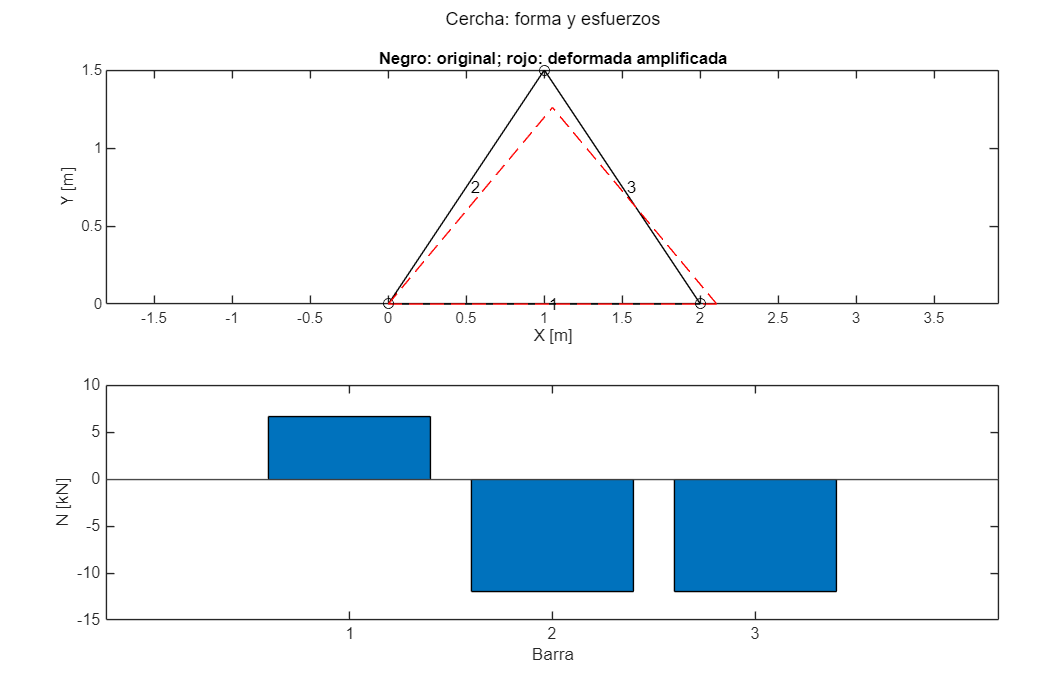

[figura,ejes] = rm_figura(2,'Cercha: forma y esfuerzos');
amplitud = max(max(nodos)-min(nodos));
escalaDeformada = 0.12*amplitud/max(max(abs(resultado.u(:))),realmin);
hold(ejes(1),'on');
for i=1:size(barras,1)
    ix=barras(i,:); p=nodos(ix,:); pd=p+escalaDeformada*resultado.u(ix,:);
    if size(nodos,2)==2
        plot(ejes(1),p(:,1),p(:,2),'k-o');
        plot(ejes(1),pd(:,1),pd(:,2),'r--');
        text(ejes(1),mean(p(:,1)),mean(p(:,2)),sprintf(' %d',i));
    else
        plot3(ejes(1),p(:,1),p(:,2),p(:,3),'k-o');
        plot3(ejes(1),pd(:,1),pd(:,2),pd(:,3),'r--');
    end
end
axis(ejes(1),'equal'); title(ejes(1),'Negro: original; rojo: deformada amplificada');
if size(nodos,2)==3, view(ejes(1),35,24); grid(ejes(1),'on'); zlabel(ejes(1),'Z [m]'); end
xlabel(ejes(1),'X [m]');ylabel(ejes(1),'Y [m]');
bar(ejes(2),(1:size(barras,1))',resultado.N/1000);
yline(ejes(2),0,'Color',[.35 .35 .35]); ylabel(ejes(2),'N [kN]'); xlabel(ejes(2),'Barra');

## Funciones utilizadas

rm_cercha: resuelve el equilibrio de una red de barras. Aquí usa tus nodos y apoyos para obtener N y u.

NaN: representa un valor no definido. Aquí marca una dirección sin restricción en los apoyos.

size: cuenta filas y columnas. Aquí determina cuántas barras se dibujan.

norm: calcula una longitud vectorial. Aquí permite formar la longitud y dirección de cada barra dentro del cálculo.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Cerchas planas o espaciales, nudos articulados, cargas nodales, barras prismáticas y elasticidad lineal. No incluye flexión de barras, grandes desplazamientos ni verificación de pandeo.

Conexión con lo anterior: Cada barra usa N=EF·epsilon del capítulo 1; aquí se añade la compatibilidad geométrica entre nodos.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 02: calculo completado.');

Capitulo 02: calculo completado.
